# Simulation of Laser Induced Interstitial Thermotherapy （LITT）

## Introduction

Laser-Induced Interstitial Thermotherapy (LITT) has emerged as a revolutionary, minimally invasive medical procedure for treating various types of tumors, including those in the liver, head, neck, and brain, as well as benign prostatic hyperplasia (BPH). The procedure involves inserting a laser applicator into the targeted tissue and utilizing laser energy to generate heat, leading to immediate or delayed tissue destruction. Despite its promising applications, ensuring the safety of LITT treatment remains a critical concern, particularly in preventing damage to healthy or sensitive structures like blood vessels and nerves.

To address these challenges, this simulation project aims to optimize the LITT process by modeling the intricate interactions between laser light and biological tissues. We will focus on key parameters such as laser power, exposure time, and tissue properties like thermal conductivity and absorption coefficients. By employing computational methods like Monte Carlo simulations and Finite Difference Analysis (FDA), we intend to solve the heat equation in a biological medium, thereby gaining insights into the spatial temperature and damage distribution during the LITT procedure.

Our current work utilizes a two-dimensional axisymmetric model, but future iterations will incorporate three-dimensional models and asymmetric laser designs. We also plan to integrate control algorithms, including PID, LQR, and optimization controls, to adapt laser parameters in real-time for optimal treatment outcomes. Furthermore, the project will explore safety margins by simulating potential risks, such as overheating and thermal damage to adjacent tissues. Through these simulations, we aim to provide quantitative metrics for a new concept of applied laser dosage, thereby enhancing the efficacy and safety of LITT treatments.

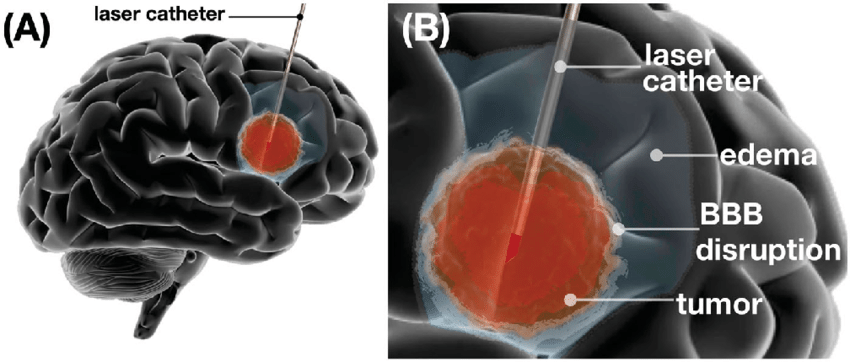

clc
clear all；

% Setting the stopwatch to view the calculated time
tic

## Initialization parameters

Different kinds of laser devices have been suggested for the internal therapy of extensive lesions. One such device is the ring-mode applicator, which not only emits radiation in a circular pattern but also has a significant forward direction. Subsequent advancements led to the creation of the scattering dome applicator, which features a uniformly distributed radiation field with varying active lengths. This equipment comes with built-in cooling capabilities. As a result, the boundary between the applicator and the tissue is not exposed to high temperatures, minimizing the risk of damage.

 The internal light intensity, or interstitial fluence rate $$\Psi(\mathrm{r}, \mathrm{z})\left[\mathrm{Wcm}^{-2}\right]$$, was determined through Monte-Carlo simulations that traced the paths of individual photons. These simulations were based on the optical properties of the tissue that had been measured. To account for the spatial variations in these optical properties and to facilitate the computation of heat conduction, the area of focus was divided into cylindrical volume units, also known as voxels. Each voxel was assigned its own unique optical and thermal characteristics. This cylindrical setup allows for the calculation of most standard interstitial application systems, with the exception of side-firing applicators and those with non-cylindrical shapes.

The light source is configured as a cylinder with a diameter of 1.8 mm and a length of 7 mm. Light is emitted uniformly along the Z-axis of the cylinder. The radial emission angle φ ranges from 0 to 360 degrees and is randomly and uniformly distributed. The axial divergence angle is also randomly and uniformly distributed between -90 and 90 degrees. The total number of emitted photons is 200,000.

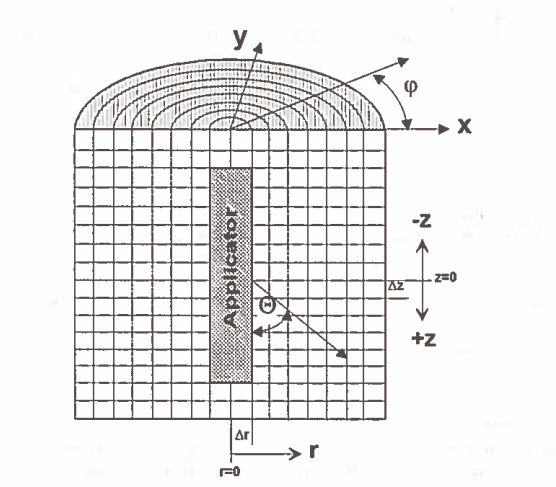

% Dimensional parameters

diameter = 1.8;          % 光纤直径
cylinder_length = 7;     % 光纤长度
Power=12;                 % 光纤功率
delta_t=0.1;             % 计算最小时长

## Monte_Carlo photon distribution calculation

#### BASIC PARAMETER

#### Absorption coefficient

`The question of whether a photon is absorbed or scattered at a new location is determined by comparing a random number `$\xi 1 \in(0,1)$ `with the probabilities for absorption and scattering processes. These probabilities are developed using a Taylor series expansion, and are applicable for small step sizes.`


$$P_{\text {absorption }}=1-\exp \left(-\mu_{\mathrm{a}} \Delta s\right)=\mu_{\mathrm{a}} \Delta \mathrm{s}$$


`If `$ \( \xi_1 < P_{\text{absorption}} \)$`, then absorption occurs. If `$\( P_{\text{absorption}} \leq \xi_1 \leq P_{\text{scattering}} + P_{\text{absorption}} \)$`, then scattering takes place.`

#### Scattering coefficient

$\mathrm{p}_{\text {scattering, } \mathrm{HG}}=1-\exp \left(-\mu_s \Delta \mathrm{s}\right)=\mu_s \Delta \mathrm{s}$; 

 $\mathrm{p}_{\text {sacattering, Iso }}=1-\exp \left(-\mu_3^{\prime} \Delta s\right) \approx \mu_3^{\prime} \Delta s$;

% Monte_Carlo Calculation parameters
mu_a = 0.19;                % 吸收系数，单位1/mm
mu_s = 43.2 ;               % 约化散射系数，单位1/mm
g = 0.99;                   % 各向异性参数
mu_s_prime = mu_s * (1 - g);
mfp = 1 / (mu_a + mu_s_prime);  % 平均自由程
delta_s = min(0.25, mfp / 10);   % step size

Nphoton = 2e5;                  
power_per_photon=(Power*delta_t)/Nphoton;

#### New angle after collision

`In scattering events, the new direction of the photon relative to its old direction is calculated using the Henyey-Greenstein phase function applied to the probability density function. The axial angular change is represented by `$\( \cos \Theta_{\text{rel}} \)$`, and the radial angular change is given by `$\( \phi_{\text{rel}} = 2\pi \xi_3 \).$


$$\cos \Theta_{\text {ral }}=\frac{1}{2 g_{\mathrm{HO}}}\left(1+g_{\mathrm{HO}}^2-\left[\frac{1-g_{\mathrm{HO}}^2}{1+g_{\mathrm{HO}}-2 g_{\mathrm{HO}} \xi_2}\right]^2\right) \quad \varphi_{\text {rel }}=2 \pi \xi_3$$


#### Photon movement （New displacement after collision）

The tracking involves following the trajectory of emitted photons as they move through the tissue. A fixed-step method is employed, where the step size is determined by the actual mean free path given by the optical parameters. Ideally, the normal step size should be at least ten times smaller than the mean free path. A comparison between the applied Henyey-Greenstein phase function and the reduced scattering coefficient can be seen in the results. The change in$ \( \Delta s \)$ for each photon is calculated using a random number $(\xi)$.


$$\Delta s \leq \frac{1}{10 \cdot\left(\mu_1+\mu_1\right)}$$



$$\Delta \mathrm{s}=\Delta \mathrm{s} \cdot(1+0.25 \cdot(1-2 \xi))$$


absorbed_photons=Monte_Carlo(Nphoton, diameter, cylinder_length, mu_a, mu_s, mu_s_prime, delta_s, mfp, g);
X = absorbed_photons(:,1);
Y = absorbed_photons(:,2);
Z = absorbed_photons(:,3);

### Plotting the results of Monte_Carlo photon distribution calculations

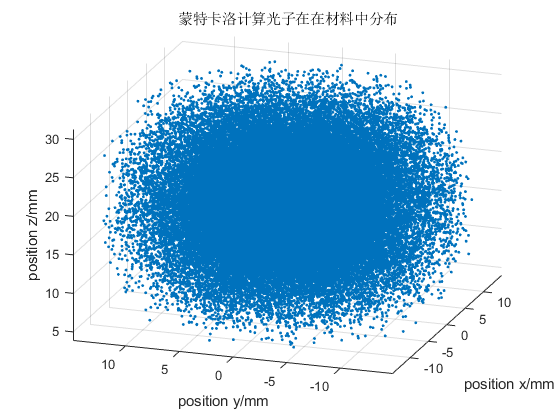

scatter3(X,Y,Z,5,'filled')
grid on;

xlabel('position x/mm ')
ylabel('position y/mm')
zlabel('position z/mm')
title('蒙特卡洛计算光子在在材料中分布')
xlim([-14.9 14.9])
ylim([-14.9 14.9])
zlim([3.9 31.3])
view([-71.1 26.2])

## Meshing (2D-coordinate system of columns)

Coordinate Transformation: The position of the photon in space is transformed from Cartesian coordinates to cylindrical coordinates. 

Grid Partitioning Logic: The grid is logically divided based on cylindrical coordinates. The angular division splits $\(2\pi\)$ into a fixed number of angles. The divisions in the$ \(r\)$ (radial) and $\(z\) $(axial) directions should be based on the computational scale being used.

The computational results from the Monte Carlo simulation are ultimately projected onto the$ \(r-z\) $ plane, where the average values are calculated.

% 组织网格计算精度
voxel_dim_r=0.1;
voxel_dim_theta=(2*pi)/100;
voxel_dim_z=0.1;
voxel_t=1;

% 组织网格计算范围
cal_rang_r=round(max(abs(absorbed_photons(:,1))));
cal_rang_theta=2*pi;
cal_rang_z=round(max(abs(absorbed_photons(:,3))));
cal_rang_t=3000;

% Coordinate system of columns
r=0:voxel_dim_r:cal_rang_r;
r_length=(cal_rang_r)/voxel_dim_r;

theta=0:voxel_dim_theta:2*pi;
theta_length=round((2*pi)/voxel_dim_theta);

z=-cal_rang_z:voxel_dim_z:cal_rang_z;
z_length=(cal_rang_z)/voxel_dim_z;

t=0:voxel_t:cal_rang_t;
t_length=cal_rang_t/voxel_t;
t_shut_down=2000;

% 坐标系转换笛卡尔-柱坐标
absorbed_photons_r = coordinate_conversion(absorbed_photons);

## Heat Source and Heat distribution (2D-coordinate system of columns)

### Heat generated by photons

In the event of absorption, the energy of the photon is stored in the corresponding voxel. The photon energy $\( E_{\text{photon}} \) $is determined based on the pre-set laser power $\( P_{\text{laser}} \)$, the total number of generated photons$ \( N_{\text{photon}} \)$ within a given time interval, and the length of that time interval$ \( \Delta t \)$.


$$E_{\text {photon }}=\frac{P_{\text {laser }} \Delta t}{N_{\text {photon }}}$$


% 热量空间分布矩阵
Q_space=zeros(r_length,theta_length,z_length);
Q_slide_one_side=zeros(r_length,z_length);

[Sum_Q_slide_sym,total_sum_Q,Sum_Q_slide]=Heat_distribution(Nphoton,absorbed_photons_r,voxel_dim_r,voxel_dim_z, r_length,theta_length,z_length,Q_space);

The simulation is conducted using MATLAB software. The distribution of laser energy within the tissue is shown in the aforementioned images. These results are obtained after tracking$ \(2 \times 10^5\)$ photons and represent the distribution of photon counts in each voxel along the fiber cross-section. The subsequent image shows the distribution of laser energy along the radius at the cross-section. As can be seen from the graph, the visible penetration depth of the laser (where the photon density drops to 1% of its peak value) is approximately 12 mm in radius.


$$Q_{t, z 1}=\frac{N_{\text {alsorbed } r, z t} E_{\text {plivoton }}}{V_{t, 2} \Delta t}$$
   

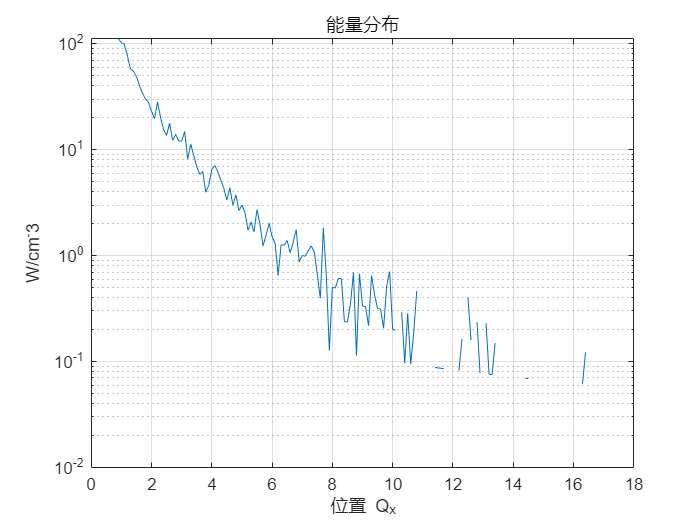

Ephonton=Power*voxel_t/total_sum_Q;

%一侧的能量分布
Ephonton_test=Ephonton;

for i0=1:r_length
    for i1=1:z_length
        
        voxel_size=voxel_dim_r*voxel_dim_z*pi*(i0*voxel_dim_r);
        
        Q_slide_one_side(i0,i1)=(Sum_Q_slide(i0,i1)*Ephonton_test)/(voxel_size*voxel_t);%*power_per_photon;

    end
end

Q_slide=sym_packing(Q_slide_one_side);

% 绘图
energy_distribution_sym=squeeze(Q_slide(:,z_length/2))*1e3;
energy_distribution=squeeze(Q_slide_one_side(:,z_length/2))*1e3;
semilogy(r(2:end),energy_distribution);
xlabel('位置 Q_x')
ylabel('W/cm^-3')
grid on
title('能量分布')

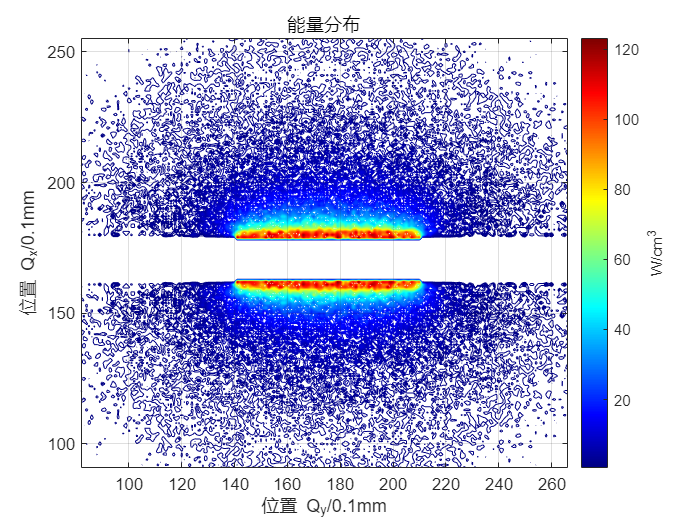

% 绘图 
figure(2);
contour(Q_slide*1e3,200)
c = colorbar;
c.Label.String = 'W/cm^3';
xlim([82 266])
ylim([91 255])
ax = gca;
chart = ax.Children(1);
xlabel('位置 Q_y/0.1mm')
ylabel('位置 Q_x/0.1mm')
grid on
title('能量分布')


Q_slide_t = heat_with_t(Q_slide,t_length,r_length,z_length,t_shut_down);


## Temperature Calculation

### THERMAL TISSUE PROPERTIES

The temperature dependent thermal tissue parameters were finally given by: 


$$\begin{array}{ll}
c(T)=4.19\left(0.37+0.63 \mathrm{k}_{\mathrm{c}} \mathrm{W}\right) & {\left[\mathrm{Jg}^{-1} \mathrm{~K}^{-1}\right]} \\
\lambda(\mathrm{T})=4.19\left(0.133+1.36 \mathrm{k}_{\mathrm{\alpha}} \mathrm{W}\right) \cdot 10^{-3} & {\left[\mathrm{WK}^{-1} \mathrm{~cm}^{-1}\right]} \\
\rho(\mathrm{T})=1.3-0.3 \mathrm{k}_\rho \mathrm{W} & {\left[\mathrm{gcm}^{-3}\right]}
\end{array}$$


Temperature dependent dimensionless correction factors were heuristically introduced to the calculation of the thermal tissue parameters, taking into consideration that the approximations for biological tissue were derived at room temperature:


$$
k_c=\left(1+1.01610^{-4 .}\left(\mathrm{T}-20^{\circ} \mathrm{C}\right)\right) \\
 k_\lambda=\left(1+1.78 \cdot 10^{-3}\left(\mathrm{~T}-20^{\circ} \mathrm{C}\right)\right) \\
 k_p=\left(1-4.9810^{-4 .}\left(\mathrm{T}-20^{\circ} \mathrm{C}\right)\right)
$$


W=0.83;                         % 组织含水量

lamda=4.19*(0.133+1.36*W)*1e-4; % 热传导系数
c=4.19*(0.37+0.63*W);           % 材料比热容
density=(1.3-0.3*W)*1e-1;        % 密度

### Differential Equation

To determine the actual temperature distribution within the tissue, it's necessary to numerically solve the bio-heat transfer equation. This equation typically accounts for various factors such as heat conduction, metabolic heat generation, blood perfusion, and heat loss due to convection and radiation. By solving this equation, one can obtain a more accurate representation of how temperature varies throughout the tissue in response to laser energy deposition.


$$\frac{\mathrm{dT}(\mathrm{r}, \mathrm{t})}{\mathrm{dt}}=\frac{\lambda}{\rho \mathrm{c}} \Delta \mathrm{T}(\mathrm{r}, \mathrm{t})+\frac{\mathrm{Q}(\mathrm{r}, \mathrm{t})}{\rho \mathrm{c}}$$



$$\Delta=\frac{\delta^2}{\delta x^2}+\frac{\delta^2}{\delta y^2}+\frac{\delta^2}{\delta z^2} \quad \text { Laplace operator }$$



$$Q=\mu_{\mathrm{a}} \Psi(\mathrm{r}, \mathrm{t}) \quad \text { source term }\left[\mathrm{Wcm} \mathrm{cm}^{-3}\right]$$


### Numerical Calculation（Finite Difference Method）

The source term $$Q_{r, z}$$ for each voxel (centre co-ordinates $$r, z$$ ) was given by the number of absorbed photons $$\left(\mathrm{N}_{\text {absorbed }}\right)$$ the Energy of each photon $$\left(\mathrm{E}_{\text {photon }}\right)$$, the duration of a time interval of calculation $$(\Delta t)$$ and the individual voxel volume $$\left(V_{r, 2}\right)$$ :


$$Q_{r, z, t}=\frac{N_{\text {absorbed } r, z t} E_{\text {photon }}}{V_{r, z} \Delta t}$$


From these formulas the new temperature for each voxel and each time interval (before consideration of blood perfusion and heat conduction) was given by:


$$T_{r, z, t}=T_{r, z, t-\Delta t}+\frac{Q_{r, z, t} \Delta t}{\rho_{r, z, t} c_{r, z, t}}$$


The blood perfusion of the tissue was considered by an additional loss term as described in the bio heat equation. For the prostate a gland perfusion of$ $0.1 \mathrm{mlg}^{-1} \mathrm{~min}^{-1}$$ was assumed, while a perfusion of $$1.0 \mathrm{mlg}^{-1} \mathrm{~min}^{-1}$$ was applied for liver tissue . The perfusion was actually set to zero for those voxels where coagulation took place during the treatment. This was due to the shrinkage of capillary vessels corresponding with coagulation. The resulting temperature for each voxel is:


$$T_{r, z, t \text {, with perfusion }}=\frac{T_{t, z, t} \cdot V_{t, z}+T_{\text {artereial }} \frac{U_B}{60}\left(P_{r, z, t} V_{t, z} \Delta t\right)}{V_{r, z}+\frac{U_B}{60}\left(\rho_{r, z, t} V_{t, z} \Delta t\right)}$$



$$\rho_{\mathrm{r}, \mathrm{z}, \mathrm{c}} \mathrm{c}_{\mathrm{r}, \mathrm{z}, \mathrm{t}} \frac{\partial \mathrm{T}}{\partial \mathrm{t}}=\frac{\partial}{\partial \mathrm{x}}\left(\lambda_{\mathrm{t}, \mathrm{z}, \mathrm{t}} \frac{\partial \mathrm{T}}{\partial \mathrm{x}}\right)+\frac{\partial}{\partial y}\left(\lambda_{\mathrm{r}, \mathrm{z},} \frac{\partial \mathrm{T}}{\partial \mathrm{y}}\right)+\frac{\partial}{\partial \mathrm{z}}\left(\lambda_{\mathrm{r}, \mathrm{z}, t} \frac{\partial \mathrm{T}}{\partial \mathrm{z}}\right)=\frac{\partial \lambda_{t, z, t}}{\partial \mathrm{r}} \frac{\partial \mathrm{T}}{\partial \mathrm{r}}+\frac{\partial \lambda_{\mathrm{r}, \mathrm{z}, \mathrm{t}}}{\partial \mathrm{z}} \frac{\partial \mathrm{T}}{\partial \mathrm{z}}+\lambda_{\mathrm{r}, \mathrm{z}, \mathrm{t}}\left(\frac{1}{\mathrm{r}} \frac{\partial \mathrm{T}}{\partial \mathrm{r}}+\frac{\partial^2 \mathrm{~T}}{\partial \mathrm{r}^2}+\frac{\partial^2 \mathrm{~T}}{\partial \mathrm{z}^2}\right)$$


Differential terms of temperature with respect to time-space


$$\left.\left.\frac{\partial \mathrm{T}}{\partial \mathrm{t}}\right|_{t, z, \mathrm{t}+\frac{\Delta t}{2}} \approx \frac{\partial \mathrm{T}}{\partial \mathrm{t}}\right|_{t, 2, \mathrm{t}} \approx \frac{\mathrm{T}_{\mathrm{t}, \mathrm{z}, \mathrm{t}+\Delta \mathrm{t}}-\mathrm{T}_{\mathrm{t}, \mathrm{t}}}{\Delta \mathrm{t}}$$



$$\left.\frac{\partial T}{\partial r}\right|_{t, z, t}=\frac{\left(\mathrm{T}_{\mathrm{r}+\Delta r, z, t}-\mathrm{T}_{\mathrm{r}-\Delta r, z \mathrm{t}}\right)}{2 \Delta \mathrm{r}}，\left.\frac{\partial T}{\partial z}\right|_{t, z, t}=\frac{\left(T_{t, z+\Delta z, t}-T_{z, z-\Delta z, t}\right)}{2 \Delta z}$$



$$\left.\frac{\partial^2 T}{\partial r^2}\right|_{r, z, t} \approx \frac{\left(T_{r+\Delta r, z, t}-T_{r, z, t}\right) / \Delta r-\left(T_{r, z, t}-T_{r-\Delta s, z i t}\right) / \Delta r}{\Delta r}=\frac{T_{r+\Delta r, z, t}-2 T_{t, z, t}+T_{r-\Delta r, z, t}}{\Delta r^2}$$



$$\left.\frac{\partial^2 T}{\partial z^2}\right|_{r, z, t} \approx \frac{\left(T_{r, z+\Delta z, t}-T_{r, z, t}\right) / \Delta z-\left(T_{r, z, t}-T_{r, z-\Delta z, t}\right) / \Delta z}{\Delta z}=\frac{T_{t, z+\Delta z, t}-2 T_{r, z, t}+T_{r, z-\Delta z, t}}{\Delta z^2}$$


Differential term for thermal conductivity with respect to time-space


$$\left.\frac{\partial \lambda}{\partial t}\right|_{\tau, z, t} \approx \frac{\lambda_{r+y_2 \Delta r, z, t}-\lambda_{r-y_2 \Delta r, z, t}}{\Delta r}，\left.\frac{\partial \lambda}{\partial z}\right|_{t, z, t} \approx \frac{\lambda_{t, 2+y_{\Delta} \Delta z, t}-\lambda_{t, z-y_{\Delta z, t}}}{\Delta z}$$



$$\lambda_{r, z, t} \approx \frac{\lambda_{t+1 / z \Delta r, z, t}+\lambda_{t-y_z \Delta r, z, t}}{2}， \lambda_{r, z, t} \approx \frac{\lambda_{t+1 / z \Delta r, z, t}+\lambda_{t-y_z \Delta r, z, t}}{2}$$


### 
$$ \lambda_{t, z+y_{\Delta} \Delta z, 1}=\frac{\lambda_{T, z+\Delta z, t}+\lambda_{r, 2, t}}{2} ，
 \lambda_{t, z-1 / z \Delta, t}=\frac{\lambda_{t, z-z-\Delta z, t}+\lambda_{t, z, t}}{2} $$



$$ \lambda_{r+1 / 2 \Delta r, z, t}=\frac{\lambda_{r+\Delta r, z, t}+\lambda_{r, z, 1}}{2} ， \lambda_{r-1 / 2 \Delta r, z t}=\frac{\lambda_{r-\Delta r, 2 t}+\lambda_{t, 2 t}}{2} $$


### Heat carried away by circulating water

Applicators have been developed with built-in cooling features, which help to prevent the interface between the applicator and the tissue from being exposed to high temperatures, thereby minimizing thermal damage. Therefore, when calculating heat distribution, it's important to take into account the heat removal process facilitated by the cooling fluid.

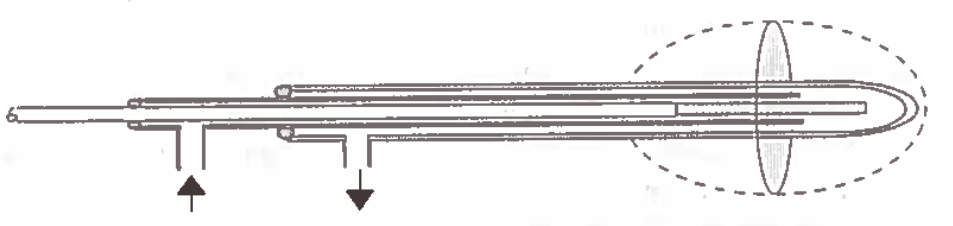

In this section, the first step is to define the boundary conditions for the cooling fluid. Next, the rate at which the cooling fluid removes heat from the system needs to be specified. The rate of temperature change in the system during this process is related to the perfusion rate and the temperature difference at that moment between the tissue and the applicator. The system's heat distribution can be calculated through the following process, which takes these factors into account.


$$\frac{\mathrm{dT}(\mathrm{r}, \mathrm{t})}{\mathrm{dt}}=-\rho v_{\mathrm{B}}\left(\mathrm{T}(\mathbf{r}, \mathrm{t})-\mathrm{T}_{\text {cooling water }}\right)$$


   
$$v_{\mathrm{B}} \quad \text { perfusionrate }\left[\mathrm{mlg}^{-1} \mathrm{~min}^{-1}\right]$$


Vb=0.045;
[T_slide_t] = FDM_2D(Q_slide_t,Vb,diameter,cylinder_length,voxel_dim_r,voxel_dim_z,voxel_t,r_length,z_length,t_length,lamda,density,c);

% Display calculation time
elapsedTime = toc;
%disp(['computing time：', num2str(elapsedTime), ' sec']);

## Computational result

We define that the water flow rate is constant and the laser heats up for 1000s, after which the laser is turned off and the system gradually cools down for 2000s, observing the process and recording the temperature change.

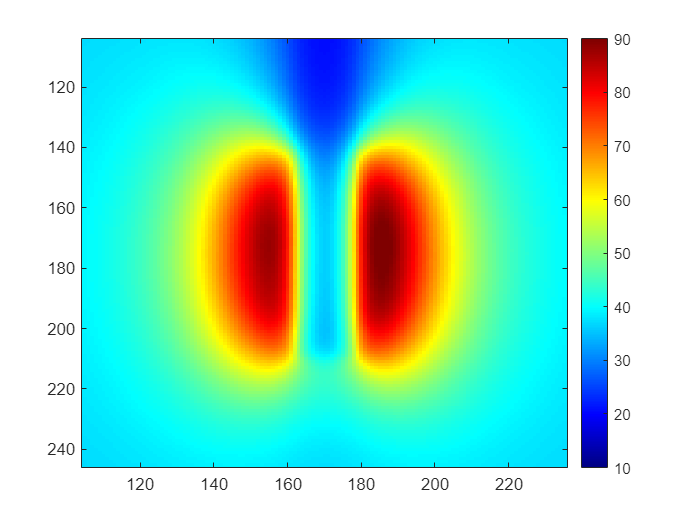

t0=961;
t00=t0/60;

figure(3);
T_slide_t1=squeeze(T_slide_t(t0,:,:));
T_line_t1=squeeze(T_slide_t(t0,:,175));
imagesc(T_slide_t1'); %,'ShowText','on'
clim([10 90]);
xlim([104 236])
ylim([104 246])
colormap('jet');
colorbar

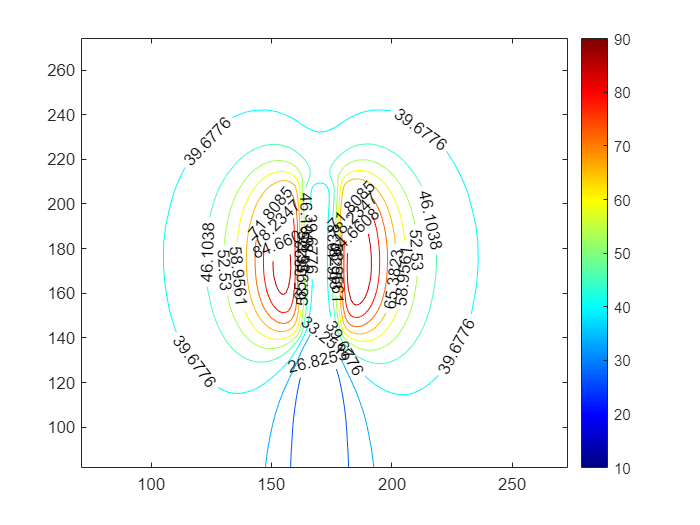

% figure(1);
T_slide_t2=contour(squeeze(T_slide_t(t0,:,:))',10,'ShowText','on');
clim([10 90]);
colorbar;
xlim([71 273])
ylim([82 274])

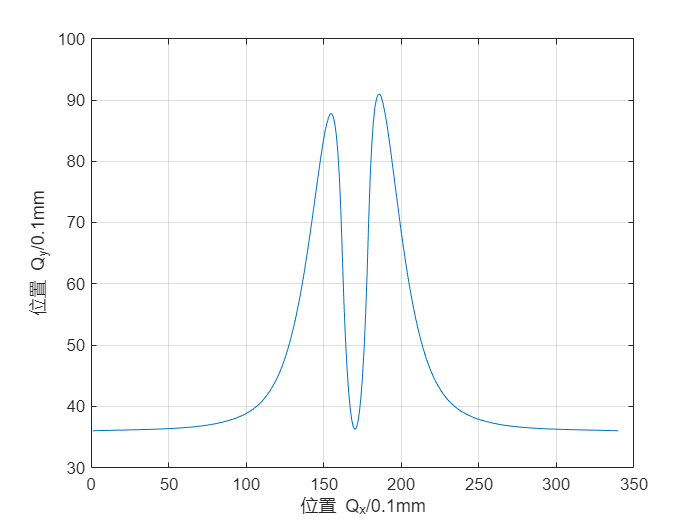

% T_slide_t0=meshc(squeeze(T_slide_t(t0,:,:)));
% clim([10 80]);
% colorbar;
% xlim([79 263])
% ylim([86 261])
% zlim([17.9 100])
% view([-68.4 24.1])
plot(T_line_t1)
txt = {'时间',t00,'s'};
 xlabel('位置 Q_x/0.1mm')
 ylabel('位置 Q_y/0.1mm')
grid on

## Reference

## Function Library

- Monte_Carlo

- InitialDirection: 围绕光纤周围定义初始随机位置

- isInCylinder*（未使用）*： 定义粒子在材料内计算  

-  scatterDirection：散射方向

- findPerpendicularVectors：寻找法线方向

- photon_path_length*（需要修改）*：光子自由程

- Heat_distribution：通过光子分布计算计算瞬时热量分布  注意：分布的边界选取需要修改

- heat_with_t

- cordinate_conversion

- sym_packing

- FDM_2D